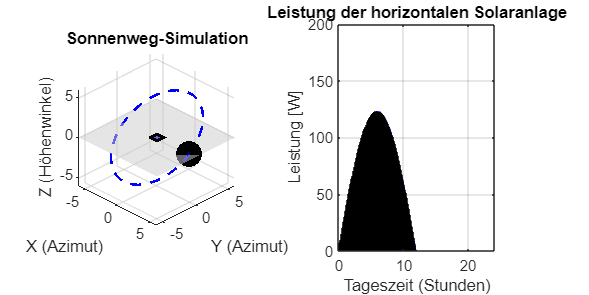

clc; clear; close all;

%% Parameter
R            = 5;                % Radius der Sonnenbahn (nur Darstellung)
inclination  = 45;               % Beliebiger Neigungswinkel (in Grad)
P_max        = 200;              % Maximale Leistung (W/m^2)
t            = linspace(0, 2*pi, 300);  % "Tag" von 0 bis 2π

% Speicher für die Leistung
E_daytime = zeros(size(t));

%% Abbildung erstellen
figure('Position',[100, 100, 1200, 600]);

% -----------------------
% (1) LINKES SUBPLOT: 3D-Szene
% -----------------------
subplot(1,2,1);  hold on;

% Beispiel: Ein Rechteck fuer eine (waagerechte) PV-Anlage
fill3([-0.5,0.5,0.5,-0.5], ...
      [-0.5,-0.5,0.5,0.5], ...
       [  0,   0,  0,   0], ...
       'blue','EdgeColor','black','LineWidth',2);

% Kreisbahn in 3D
theta = linspace(0,2*pi,100);
x_circle = R*cos(theta);
y_circle = R*sin(theta);
z_circle = R*sind(inclination).*sin(theta);
plot3(x_circle, y_circle, z_circle, '--b','LineWidth',1.5);

% Horizont (graue Platte)
[X,Y] = meshgrid(linspace(-R-1,R+1,50));
Z = zeros(size(X));
surf(X, Y, Z, 'FaceColor',[0.8,0.8,0.8], ...
    'EdgeColor','none','FaceAlpha',0.5);

% Achsen & Ansicht
axis equal;
axis([-R-1, R+1, -R-1, R+1, -R-1, R+1]);
xlabel('X (Azimut)'); ylabel('Y (Azimut)'); zlabel('Z (Höhenwinkel)');
grid on; view(45,30);
title(['Sonnenweg-Simulation']);

% Sonne als Markersymbol
sun = plot3(NaN,NaN,NaN,'o','MarkerSize',15,'MarkerEdgeColor','black');

% -----------------------
% (2) RECHTES SUBPLOT: Balkendiagramm (Leistung)
% -----------------------
subplot(1,2,2);
bar_plot = bar(0,0,'FaceColor','blue');
xlabel('Tageszeit (Stunden)');
ylabel('Leistung [W]');
title('Leistung der horizontalen Solaranlage');
ylim([0, 1*P_max]);  % Skaliere Achse entsprechend
grid on;

%% Animation & Leistung berechnen
for i = 1:length(t)
    % (a) 3D-Position
    x_sun = R * cos(t(i));
    y_sun = R * sin(t(i));
    z_sun = R * sind(inclination) * sin(t(i));
    
    % (b) Höhen-Anteil => Leistung
    % Hier interpretieren wir z_sun > 0 als "über dem Horizont"
    if z_sun > 0
        % Ursprünglich: P_t = P_max*sind(z_sun)
        % => jetzt x5:
        P_t = 10 * P_max * sind(z_sun);  
    else
        P_t = 0;
    end
    E_daytime(i) = P_t;
    
    % (c) Farbe Sonne
    if z_sun < 0
        sun_color = 'black';
    else
        sun_color = 'yellow';
    end
    
    % (d) Plot updaten
    set(sun, 'XData',x_sun, 'YData',y_sun, 'ZData',z_sun, ...
        'MarkerFaceColor',sun_color);
    
    % Zeit-Achse: 0..2π ~ 24h => t(i)*(12/π) in Stunden
    set(bar_plot, 'XData', t(1:i)*(12/pi), 'YData', E_daytime(1:i));
    
    drawnow;
    pause(0.04);
end


%% Gesamte Tagesleistung 
dt_hours        = 24 / length(t);
total_energy_Wh = sum(E_daytime) * dt_hours;

disp('Simulation abgeschlossen.');

Simulation abgeschlossen.


fprintf('Gesamt-Tagesleistung: %.1f Wh\n', total_energy_Wh);

Gesamt-Tagesleistung: 939.3 Wh
